# Ejercicios modelos

## Ejercicio 1:

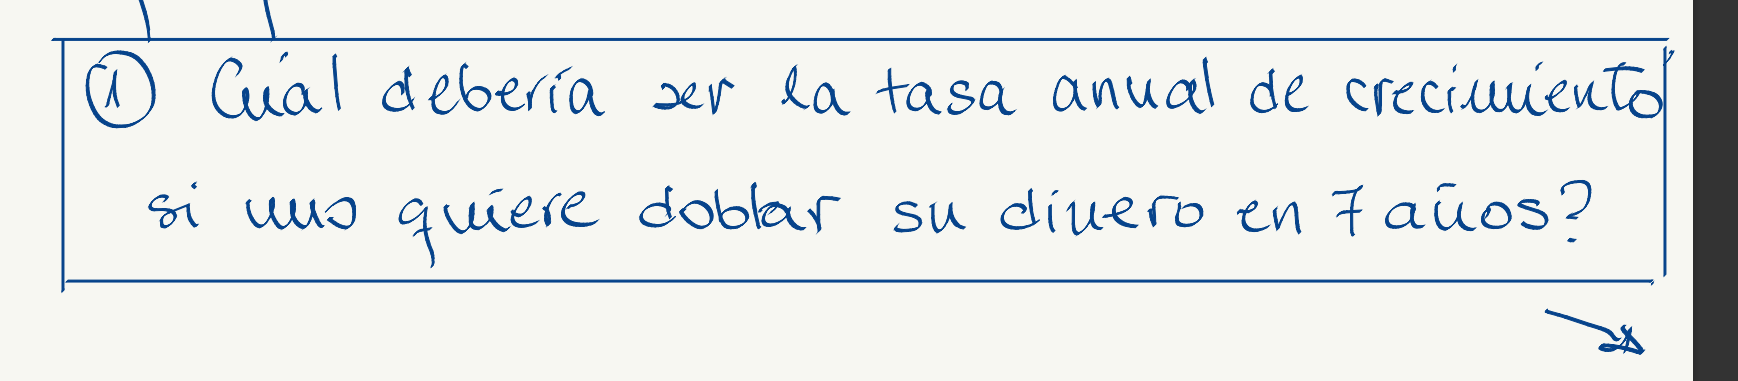

Modelo de crecimiento exponencial.


$$\begin{array}{l}
\frac{\textrm{dM}}{\textrm{dt}}=r\cdot M\\
\textrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
syms P(t) P0 t0 m

edo = diff(P, t, 1) == m*P;
cond = [P(t0)==P0];

P(t) = dsolve(edo, cond);
P(t) = collect(P(t), [m,t])     % para sacar factor comun

$$P(t) = P_{0}\,{\mathrm{e}}^{m\,t}\,{\mathrm{e}}^{-m\,t_{0}}$$

No hay un estado estacionario (equilibrio evidente).

El proceso es igual que el del modelo anterior con el signo negativo.

#### Tasa de duplicación: 

Tiempo que transcurre hasta que la cantidad física es el doble de la inicial.


$$M\left(t\right)=2\cdot M_o$$


tasa_dup = solve(P == 2*P0, t)

$$tasa\_dup = \frac{\log\left(2\,{\mathrm{e}}^{m\,t_{0}}\right)}{m}$$

Si quiero doblar el dinero en 7 años $\textrm{tasa}\;\textrm{de}\;\textrm{duplicación}=7$. Despejo r de la ecuación.

tasa_dup = subs(tasa_dup, t0, 0);
r_dup = double(solve(tasa_dup == 7,m))

r_dup = 0.0990

P = subs(P, [t0 P0 m], [0 1 r_dup]); % sustituyo en M los valores obtenidos e iniciales

Da resultado $r=0\ldotp 0990$ , con una **tasa anual de crecimiento del 9.9% **se duplicará el dinero en 7 años.

#### 3. Gráfica

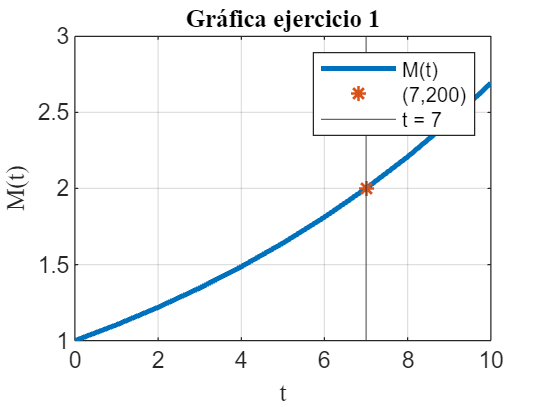

M_values = subs(P, t, 0:1:10);
plot(0:1:10, P(0:1:10), 'LineWidth', 2);
hold on
xline(7)
plot(7,P(7),'*','LineWidth',1)
xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Gráfica ejercicio 1','FontName','latex');
legend('M(t)','t = 7','(7,200)');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra y para r = 0.0990, en 7 años, el ahorro se multiplica por dos. Comienza en 1 y acaba en 2.

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=r\cdot M\\
M=0
\end{array}$$


syms P m
eq =m*P == 0;
P = solve(eq,P)

$$P = 0$$

Observamos en la gráfica que efectivamente se estabiliza, cuando $M=0$ en cualquiera de los casos. El estado estacionario o de equilibrio es **trivial**.

### Por circuito en Simulink

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 10;
solver.step = 1;

Nombre del modelo

model_name = "modelo3";

Condiciones iniciales y constantes del modelo:

k_values =  0;
r_values = 0.0990;
ic_values = [0 100];
t_values = 0:5:100;
[m, n] = size(k_values);

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;
P1 = signals{1}.Values.Data;
P = signals{2}.Values.Data;
signal_time = signals{1}.Values.Time;

#### Gráfica 1

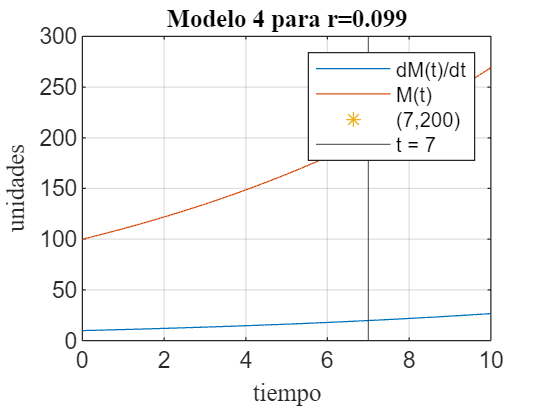

[m, n] = size(P1);
for i =1:1
    figure
    plot(signal_time, P1(:,i))
    hold on
    plot(signal_time, P(:,i))
    grid on
    xlabel("tiempo","FontName","latex");
    ylabel("unidades","FontName","latex");
    title(['Modelo 4 para r=' num2str(r_values(i))],'FontName','latex');
    xline(7);
    plot(7,2*ic_values(2),'*');
    legend('dM(t)/dt','M(t)','t = 7','(7,200)');
    hold off
end 

## Ejercicio 2

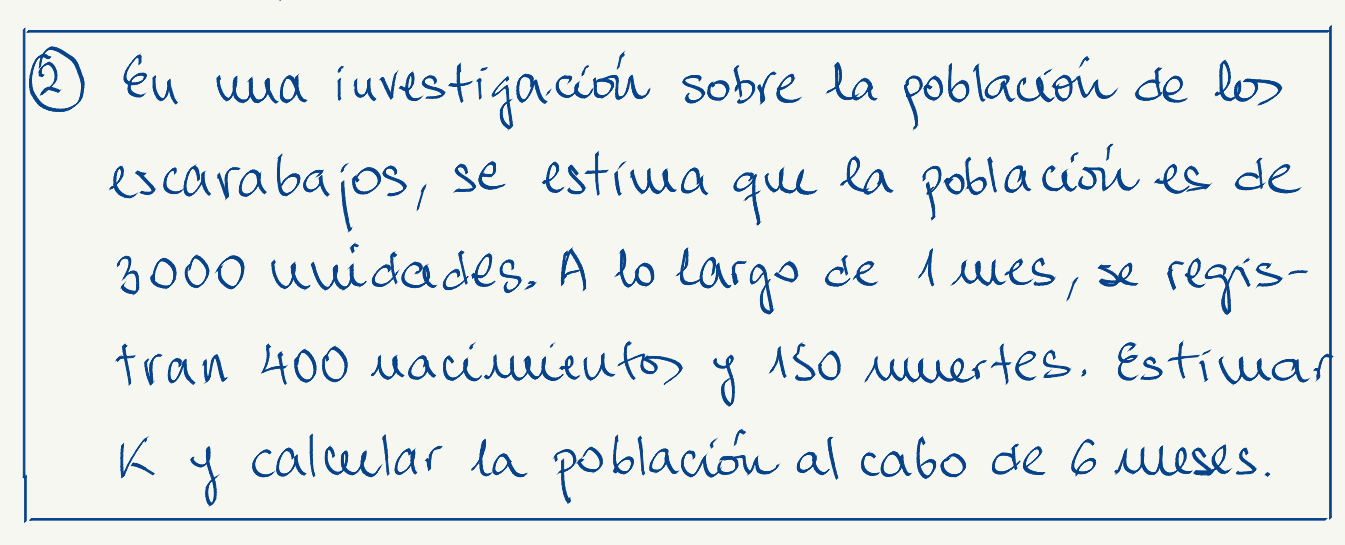

Es un modelo de crecimiento de población con tasas de nacimientos y mortalidad.


$$\begin{array}{l}
\frac{\textrm{dP}}{\textrm{dt}}=\left(b-d\right)\cdot P\\
b=\textrm{ratio}\;\textrm{de}\;\textrm{nacimiento}\;\\
d=\textrm{ratio}\;\textrm{de}\;\textrm{muerte}\;\\
k=b-d\\
\frac{1}{d}=\textrm{tasa}\;\textrm{de}\;\textrm{vida}\;\textrm{útil}\;\textrm{estimada}
\end{array}$$


siendo $b=\frac{400}{3000}\;;\;d=\frac{150}{3000}$ 

clc, clear
b = 400/3000

b = 0.1333

d = 150/3000

d = 0.0500

d = b - d

d = 0.0833

P0 = 3000;
t0 = 0;

#### 1. Resolución de la EDO

syms P(t)
edo = diff(P, t, 1) == (b-d)*P;
cond = [P(t0)==P0];
P(t) = dsolve(edo, cond)

$$P(t) = 3000\,{\mathrm{e}}^{t/20}$$


$$\frac{1}{d}\;\;=\textrm{tasa}\;\textrm{de}\;\textrm{vida}\;\textrm{útil}\;\textrm{estimada}$$


vida_ue = 1/d

vida_ue = 12

La vida útil estimada es de 20meses.


$$\begin{array}{l}
\\
R_{o\;} =\;\frac{b}{d}=\textrm{nº}\;\textrm{de}\;\textrm{descendientes}\;\textrm{esperados}\;o\;\textrm{tasa}\;\textrm{de}\;\textrm{reproducción}\\
\textrm{Si}\;R_o <1\to \textrm{epidemia}\;\textrm{remite}\\
\textrm{Si}\;R_o >1\to \textrm{epidemia}
\end{array}$$


Ro = b/d

Ro = 1.6000

Como es mayor que 1, la población crece.

#### 3. Gráfica

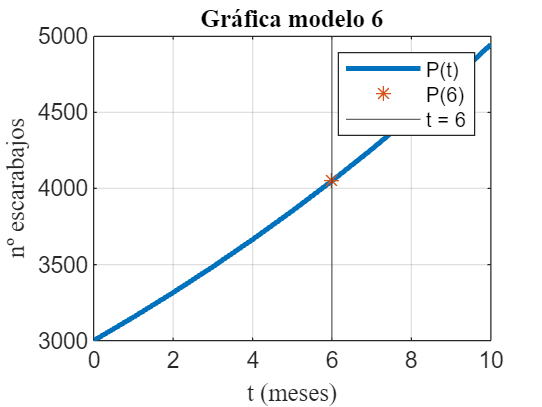

plot(0:1:10, P(0:1:10), 'LineWidth', 2);
xlabel('t (meses)','FontName','latex');
ylabel('nº escarabajos','FontName','latex');
title('Gráfica modelo 6','FontName','latex');
xline(6)
hold on
plot(6,P(6),'*')
hold on
legend('P(t)','t = 6', 'P(6)');
grid on;
hold off;

La población en 6 meses será:

double(P(6))

ans = 4.0496e+03

## Ejercicio 4

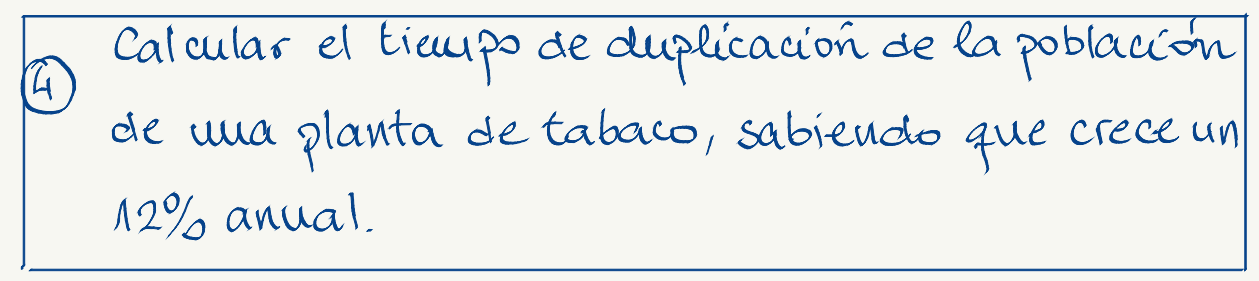

Modelo de crecimiento exponencial.


$$\begin{array}{l}
\frac{\textrm{dM}}{\textrm{dt}}=r\cdot M\\
\textrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
m = 0.12;
syms P(t) P0 t0 

edo = diff(P, t, 1) == m*P;
cond = [P(t0)==P0];

P(t) = dsolve(edo, cond);
P(t) = collect(P(t), [m,t])     % para sacar factor comun

$$P(t) = P_{0}\,{\mathrm{e}}^{\frac{3\,t}{25}}\,{\mathrm{e}}^{-\frac{3\,t_{0}}{25}}$$

No hay un estado estacionario (equilibrio evidente).

El proceso es igual que el del modelo anterior con el signo negativo.

#### Tasa de duplicación: 

Tiempo que transcurre hasta que la cantidad física es el doble de la inicial.


$$M\left(t\right)=2\cdot M_o$$


tasa_dup = solve(P == 2*P0, t)

$$tasa\_dup = \frac{25\,\log\left(2\,{\mathrm{e}}^{\frac{3\,t_{0}}{25}}\right)}{3}$$

Si quiero doblar el dinero en 7 años $\textrm{tasa}\;\textrm{de}\;\textrm{duplicación}=7$. Despejo r de la ecuación.

tiempo_dup = subs(tasa_dup, t0, 0);
double(tiempo_dup)

ans = 5.7762

Da resultado $t=5\ldotp 7762$ , con una **tasa anual de crecimiento del 12%**

Y sustituyo la tasa y los valores iniciales.

P = subs(P,[m t0 P0],[0.12 0 100])

$$P(t) = 100\,{\mathrm{e}}^{\frac{3\,t}{25}}$$

#### 3. Gráfica

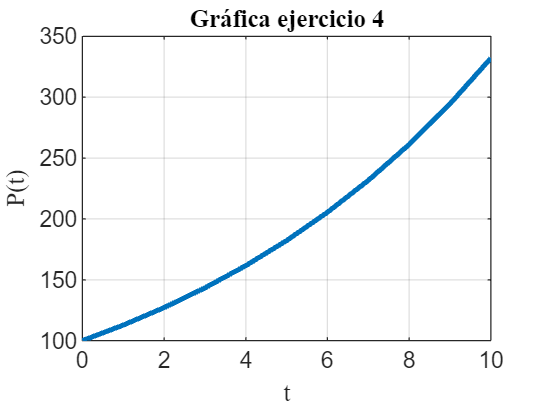

plot(0:1:10, P(0:1:10), 'LineWidth', 2);
hold on
xlabel('t','FontName','latex');
ylabel('P(t)','FontName','latex');
title('Gráfica ejercicio 4','FontName','latex');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra y para r = 0.0990, en 7 años, el ahorro se multiplica por dos. Comienza en 1 y acaba en 2.

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=r\cdot M\\
M=0
\end{array}$$


syms P m
eq =m*P == 0;
P = solve(eq,P)

$$P = 0$$

Observamos en la gráfica que efectivamente se estabiliza, cuando $M=0$ en cualquiera de los casos. El estado estacionario o de equilibrio es **trivial**.

## Ejercicio 3

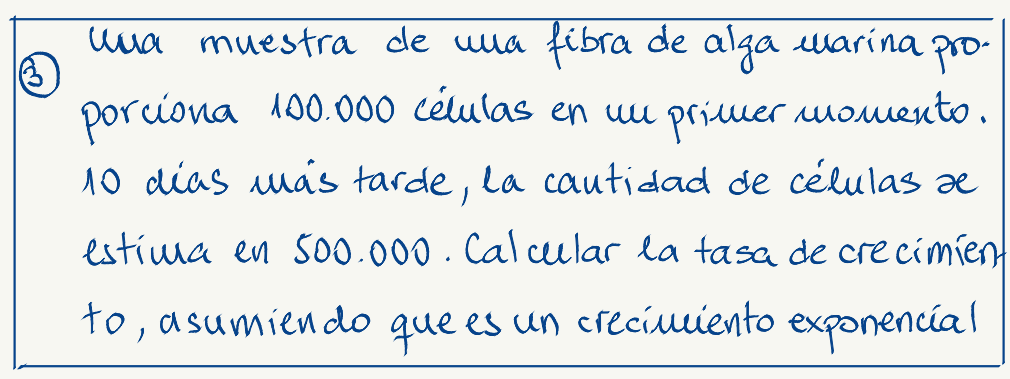

Modelo de crecimiento exponencial.


$$\begin{array}{l}
\frac{\textrm{dP}}{\textrm{dt}}=r\cdot P\\
\textrm{con}\;P\left(t_o \right)=P
\end{array}$$


#### 1. Resolución de la EDO

Sustituimos los valores iniciales.

clc, clear
syms P(t) m
P0 = 100000;
t0= 0; 

Resolvemos la EDO.

edo = diff(P, t, 1) == m*P;
cond = [P(t0)==P0];

P(t) = dsolve(edo, cond);
P(t) = collect(P(t), [m,t])     % para sacar factor comun

$$P(t) = 100000\,{\mathrm{e}}^{m\,t}$$

Para t = 10, la población es 500.000.

r_5 = solve(P(10) == 500000,m)

$$r\_5 = \frac{\log\left(5\right)}{10}$$

double(r_5)

ans = 0.1609

P = subs(P,m,r_5)

$$P(t) = 100000\,{\mathrm{e}}^{\frac{t\,\log\left(5\right)}{10}}$$

Comprobamos el resultado con la r calculada.

P(10)

$$ans = 500000$$

#### 2. Gráfica

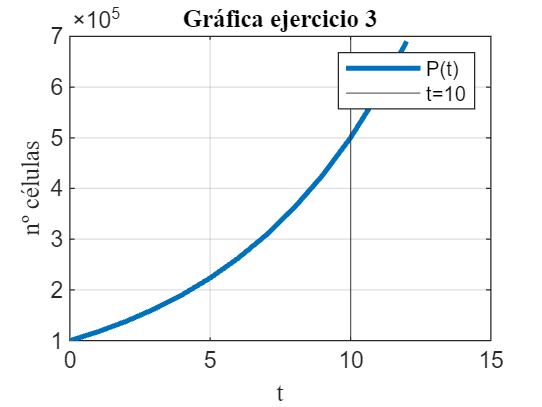

plot(0:1:12, P(0:1:12), 'LineWidth', 2);
hold on
xlabel('t','FontName','latex');
xline(10)
ylabel('nº células','FontName','latex');
title('Gráfica ejercicio 3','FontName','latex');
legend('P(t)','t=10');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra y para r = 0.0990, en 7 años, el ahorro se multiplica por dos. Comienza en 1 y acaba en 2.

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=r\cdot M\\
M=0
\end{array}$$


syms P m
eq =m*P == 0;
P = solve(eq,P)

$$P = 0$$

Observamos en la gráfica que efectivamente se estabiliza, cuando $M=0$ en cualquiera de los casos. El estado estacionario o de equilibrio es **trivial**.

## Ejercicio 5

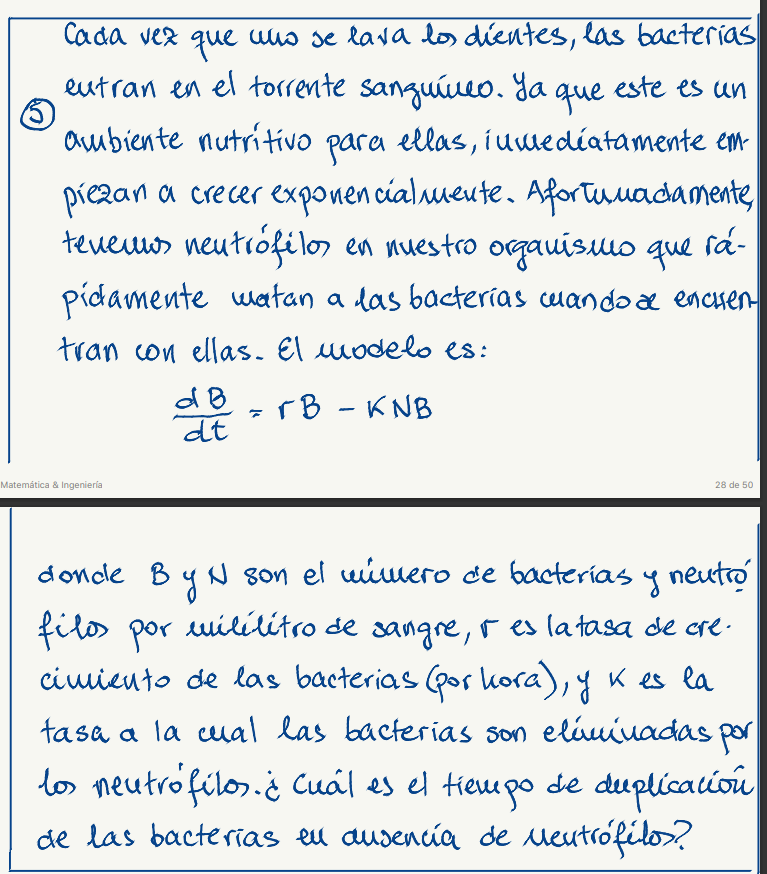

Es un modelo de crecimiento de población con tasas de crecimiento y mortalidad.


$$\begin{array}{l}
\frac{\textrm{dB}}{\textrm{dt}}=\left(r-k\cdot N\right)\cdot B\\
B=\textrm{población}\;\textrm{de}\;\textrm{bacterias}\;\textrm{en}\;\textrm{un}\;\textrm{tiempo}\;t\\
r=\textrm{tasa}\;\textrm{de}\;\textrm{crecimiento}\;\textrm{de}\;\textrm{las}\;\textrm{bacterias}\;\left(\textrm{por}\;\textrm{hora}\right)\;\\
k=\textrm{tasa}\;\textrm{la}\;\textrm{cual}\;\textrm{las}\;\textrm{bacterias}\;\textrm{son}\;\textrm{eliminadas}\;\textrm{por}\;\textrm{los}\;\textrm{neutrófilos}\\
N=\textrm{nº}\;\textrm{de}\;\textrm{neutrófilos}\\
h=r-k\cdot N\\
\frac{1}{\textrm{kN}}=\textrm{tasa}\;\textrm{de}\;\textrm{vida}\;\textrm{útil}\;\textrm{estimada}
\end{array}$$


#### 1. Resolución de la EDO

syms P(t) m d N B0
edo = diff(P, t, 1) == (m - d*N)*P;
cond = [P(0)==B0];
P(t) = dsolve(edo, cond)

$$P(t) = B_{0}\,{\mathrm{e}}^{t\,\left(m-N\,d\right)}$$


$$\frac{1}{d}\;\;=\textrm{tasa}\;\textrm{de}\;\textrm{vida}\;\textrm{útil}\;\textrm{estimada}$$


vida_ue = 1/d*N

$$vida\_ue = \frac{N}{d}$$


$$\begin{array}{l}
\\
R_{o\;} =\;\frac{b}{d}=\textrm{nº}\;\textrm{de}\;\textrm{descendientes}\;\textrm{esperados}\;o\;\textrm{tasa}\;\textrm{de}\;\textrm{reproducción}\\
\textrm{Si}\;R_o <1\to \textrm{epidemia}\;\textrm{remite}\\
\textrm{Si}\;R_o >1\to \textrm{epidemia}
\end{array}$$


Ro = m/d*N

$$Ro = \frac{N\,m}{d}$$

#### Tasa de duplicación en ausencia de neutrófilos: 

Tiempo que transcurre hasta que la cantidad física es el doble de la inicial.


$$B\left(t\right)=2\cdot B_o$$


tasa_dup = solve(P == 2*B0, t)

$$tasa\_dup = \frac{\log\left(2\right)}{m-N\,d}$$

Si no hay neutrinos:

subs(tasa_dup,N,0)

$$ans = \frac{\log\left(2\right)}{m}$$

## Ejercicio 6

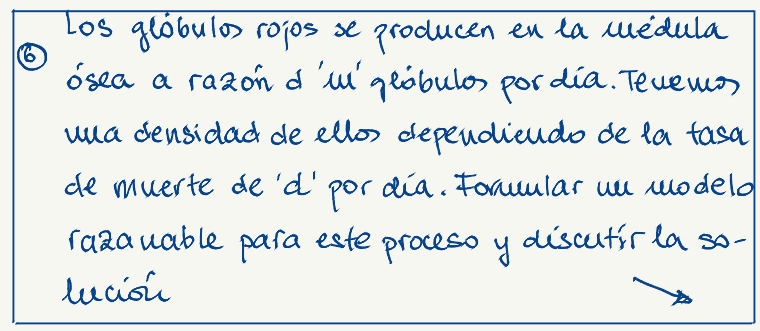

Es un modelo de crecimiento de población con tasas de nacimientos y mortalidad.


$$\begin{array}{l}
\frac{\textrm{dP}}{\textrm{dt}}=m-d\cdot P\\
b=\textrm{ratio}\;\textrm{de}\;\textrm{nacimiento}\;\\
d=\textrm{ratio}\;\textrm{de}\;\textrm{muerte}\;\\
k=b-d\\
\frac{1}{d}=\textrm{tasa}\;\textrm{de}\;\textrm{vida}\;\textrm{útil}\;\textrm{estimada}
\end{array}$$


syms P(t) m d P0
edo = diff(P, t, 1) == m - d*P;
cond = [P(0)==P0];
P(t) = dsolve(edo, cond)

$$P(t) = \frac{m-{\mathrm{e}}^{-d\,t}\,\left(m-P_{0}\,d\right)}{d}$$

## Ejercicio 7

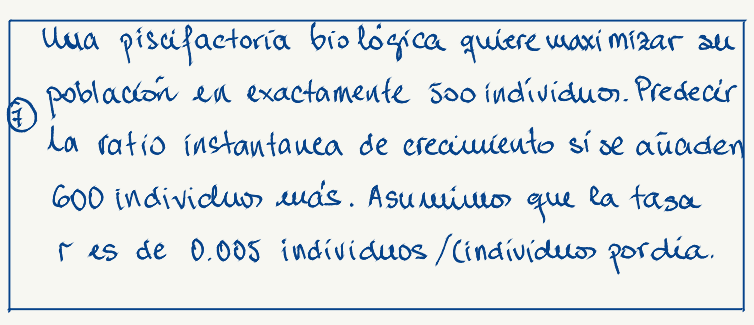

Es un modelo logístico, ya que consideramos $f\left(P\left(t\right)\right)\;$**no lineal**.


$$\frac{\textrm{dP}}{\textrm{dt}}=f\left(P\left(t\right)\right)$$



$$\textrm{con}\;f\left(P\left(t\right)\right)=k_o +k_1 P\left(t\right)+k_2 P^2 \left(t\right)+\ldotp \ldotp \ldotp$$


Solo nos quedamos hasta orden 2.


$$\frac{\textrm{dP}}{\textrm{dt}}=k_o +k_1 P\left(t\right)+k_2 P^2 \left(t\right)$$


- **Condición 1**: sin población no hay crecimiento. $\frac{\textrm{dP}}{\textrm{dt}}=$0 cuando $\mathrm{P}=0$ 

            
$$0=k_o +k_1 \cdot 0+k_2 \cdot 0\;\to k_o =0$$


- Condición 2: la población tiene un máximo. $\frac{\textrm{dP}}{\textrm{dt}}=0$ cuando $P\;=P_{\max } \not= 0$

            
$$0=k_1 \cdot P_{\max } +k_2 \cdot {P^2 }_{\max } \to k_2 =-\frac{k_1 }{P_{\max } }$$


clc, clear
syms P Pmax k0 k1 k2 
f(P) = k0 + k1*P + k2*P^2

$$f(P) = k_{2}\,P^{2}+k_{1}\,P+k_{0}$$

% condición 1
k0_subs = solve(f(0) == 0,k0);
% sustituyo
f(P) = subs(f,k0, k0_subs);
% condición 2
k2_subs = solve(f(Pmax) == 0, k2);
% sustituyo
f(P) = subs(f,k2, k2_subs)

$$f(P) = P\,k_{1}-\frac{P^{2}\,k_{1}}{\mathrm{Pmax}}$$


syms P(t) t
edo = diff(P,t,1) == f(P) % dP/dt = k*P*(1-P/Pmax) = f(P(t))

$$edo(t) = \frac{\partial }{\partial t}P\left(t\right)=k_{1}\,P\left(t\right)-\frac{k_{1}\,{P\left(t\right)}^{2}}{\mathrm{Pmax}}$$

Obtenemos la fórmula:


$$\frac{\textrm{dP}}{\textrm{dt}}=k\cdot P\cdot \left(1-\frac{P}{P_{\max } }\right)$$


### Resolución de la edo

syms P0
cond = [P(0) == P0];
P(t) = dsolve(edo,cond)

$$P(t) = \frac{\mathrm{Pmax}}{{\mathrm{e}}^{\log\left(\frac{\mathrm{Pmax}}{P_{0}}-1\right)-k_{1}\,t}+1}$$

P(t) = subs(P,[Pmax, P0, k1],[1000, 600, 0.005])

$$P(t) = \frac{1000}{{\mathrm{e}}^{\log\left(\frac{2}{3}\right)-\frac{t}{200}}+1}$$

### Estudio de estabilidadb

Para $k>0;P>0;P<P_{\max } \;\to \frac{\textrm{dP}}{\textrm{dt}}=0$

En estacionario $\frac{\textrm{dP}}{\textrm{dt}}=0\;\textrm{si}\;\;P=0\;\;o\;P=P_{\max }$

Si diferenciamos la ecuación con respecto al tiempo:


$$\frac{d^2 P}{{\textrm{dt}}^2 }=k\cdot \frac{\textrm{dP}}{\textrm{dt}}\cdot \left(1-\frac{2P}{P_{\max } }\right)$$


Para encontrar el punto de inflexión:


$$\frac{d^2 P}{{\textrm{dt}}^2 }=0$$


Que ocurre en:


$$\frac{\textrm{dP}}{{\textrm{dt}} }=0$$


o bien en:


$$\left(1-\frac{2P}{P_{\max } }\right)=0\to P=\frac{P_{\max } }{2}$$


syms P Pmax
solve(1-2*P/Pmax == 0, P)

$$ans = \frac{\mathrm{Pmax}}{2}$$

La tasa de variación es máxima en el punto de inflexión, $P=\frac{P_{\max } }{2}\to P_{\max } =2\cdot 500=1000$

Ahora la población es de $P=500+600=1100$

Sustituyendo:

0.005*1100*(1 - 1100/1000)

ans = -0.5500

## Ejercicio 8

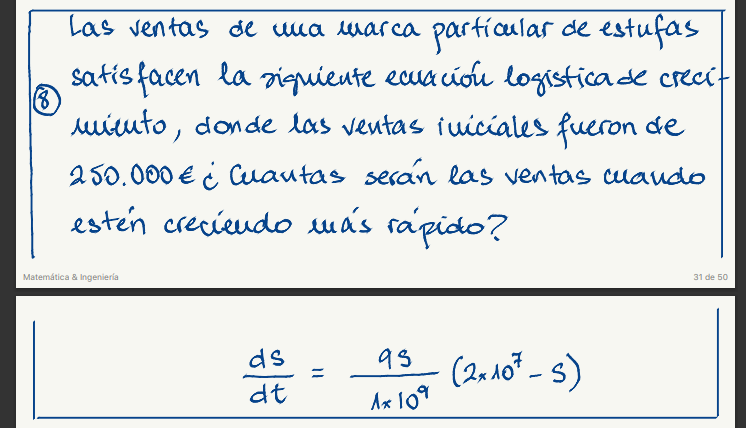

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

**Decorador de la función sim de MATLAB**

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

Se utiliza el bloque Out1 para cada señal.